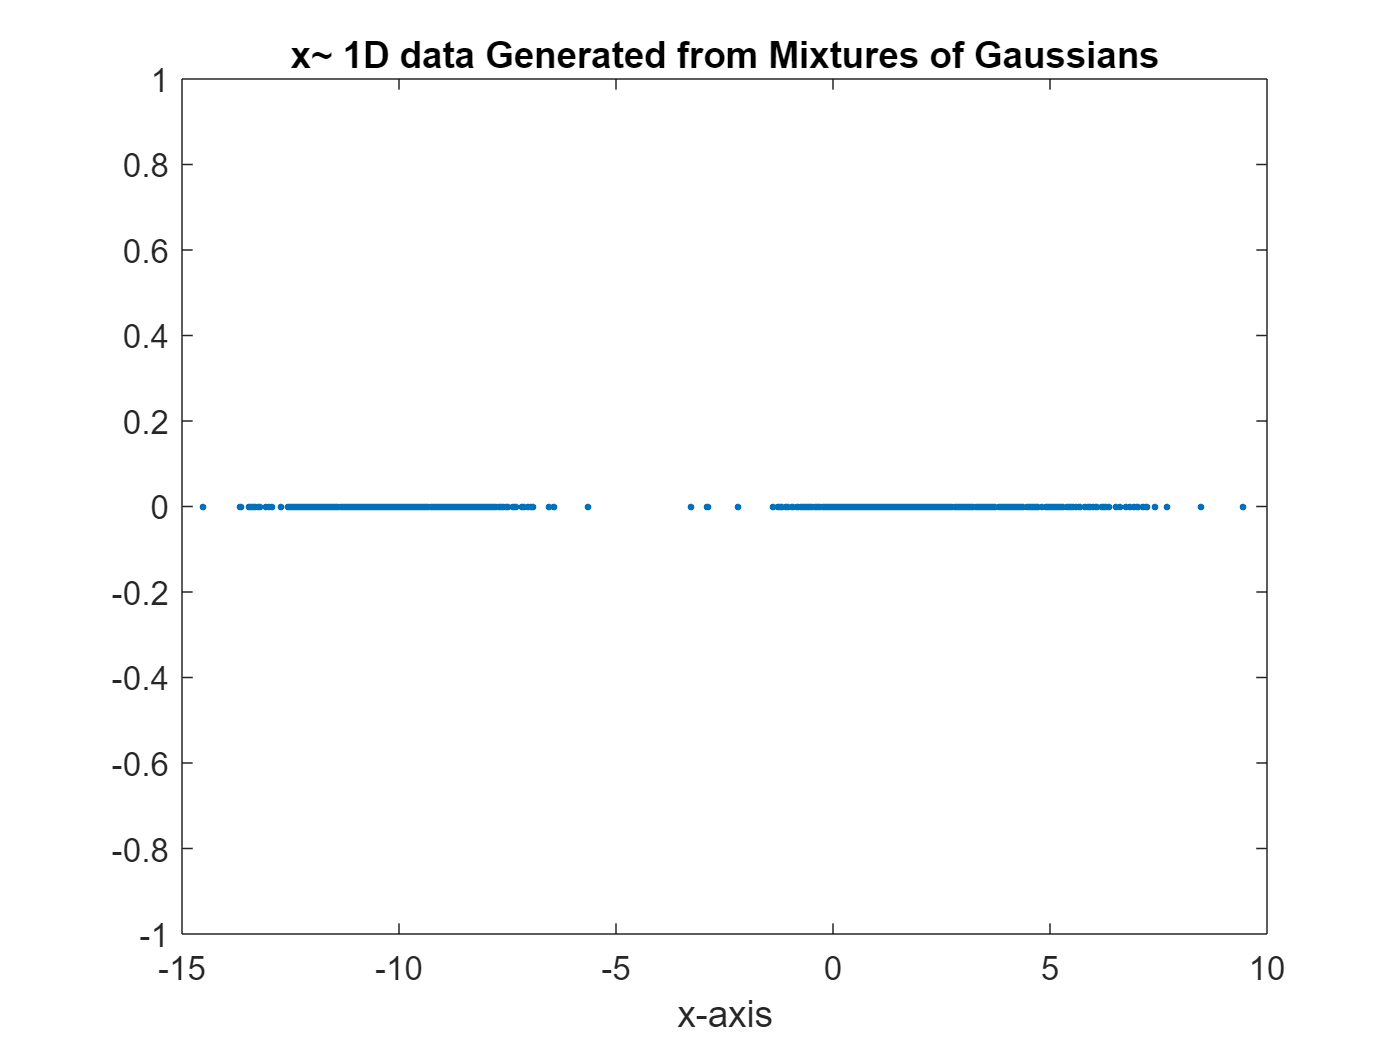

clc, clear all, close all,

N = 1000; % Specify number of samples

%% 1D case
mu=[1 -10 3];% normal distributions means
sigma=[1 2 4 ] ; %1st normal distributions variances
% Store parameters in a structure
gmmParameters.meanVectors=mu;
gmmParameters.covMatrices=sigma;
gmmParameters.priors=[0.2 0.5 0.3];%the likelihood of each distribution to be selected
% Generate 1D vector from 3 Mixtures of Gaussians
V_gaussian_1D = generateDataFromGMM_OG(N,gmmParameters,1); 

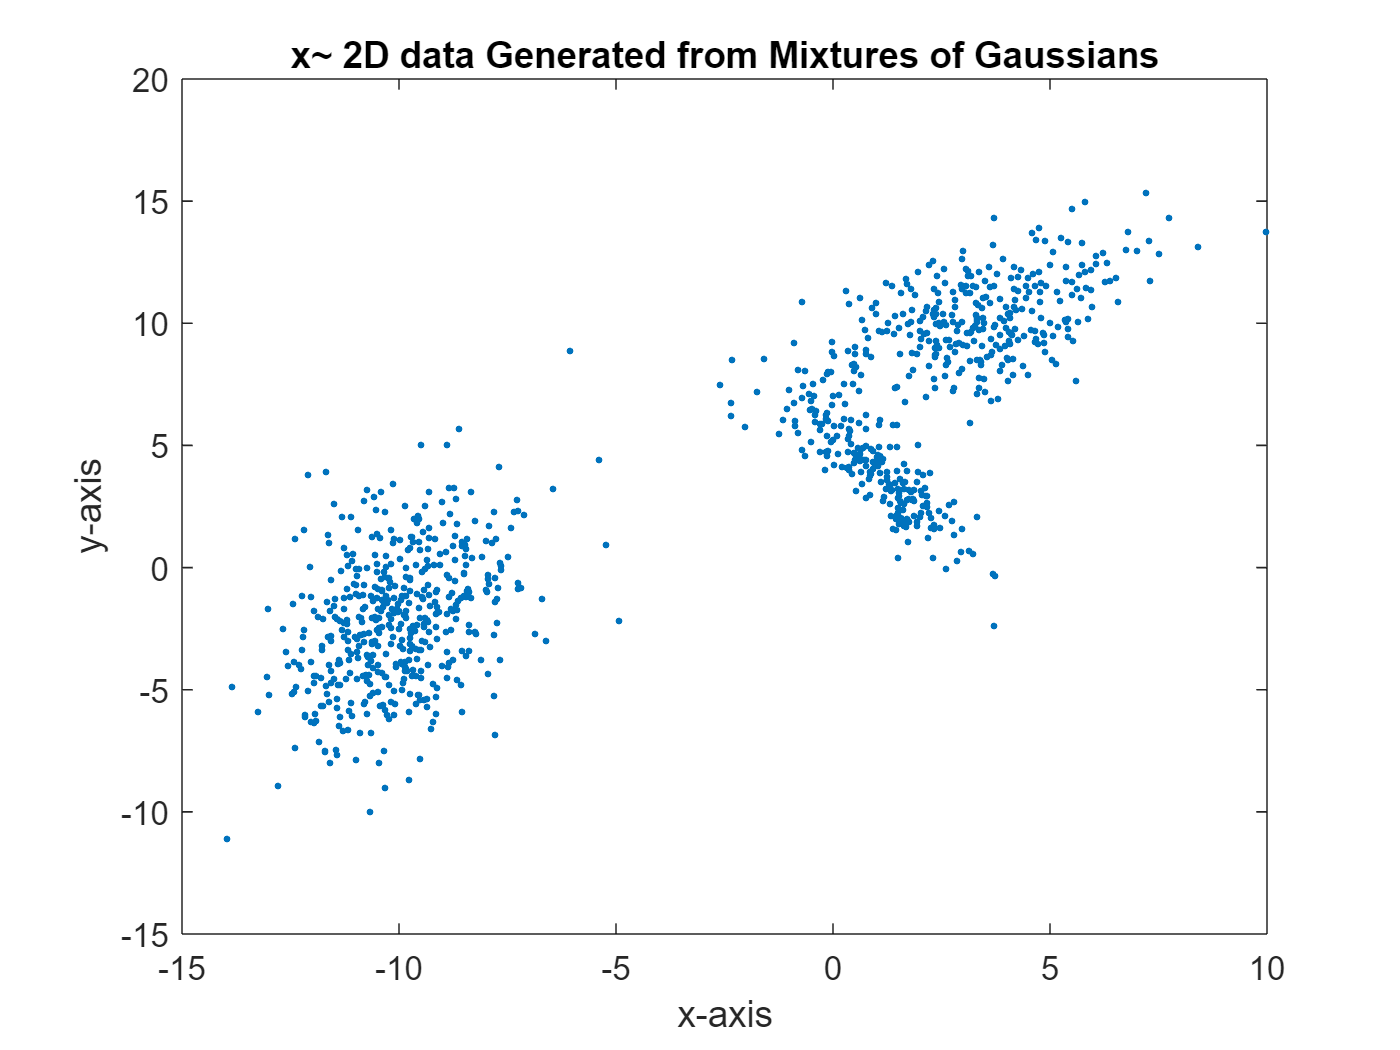


%% 2D case 
clear gmmParameters mu sigma
mu=[1 -10 3; 4 -2 10];% 3 normal distributions means of x and y axis
sigma(:,:,1)=[1 -1.5; -1.5 3] ; %1st normal distribution covariance
sigma(:,:,2)=[2 1.5; 1.5 8]; % 2nd normal distribution covariance
sigma(:,:,3)=[4 2.5; 2.5 4] ; %3rd normal distribution covariance
% Store parameters in a structure
gmmParameters.meanVectors=mu;
gmmParameters.covMatrices=sigma;
gmmParameters.priors=[0.2 0.5 0.3];%the likelihood of each distribution to be selected
% Generate 2D matrix from 3 mixtures of Gaussians
V_gaussian_2D = generateDataFromGMM_OG(N,gmmParameters,1); 

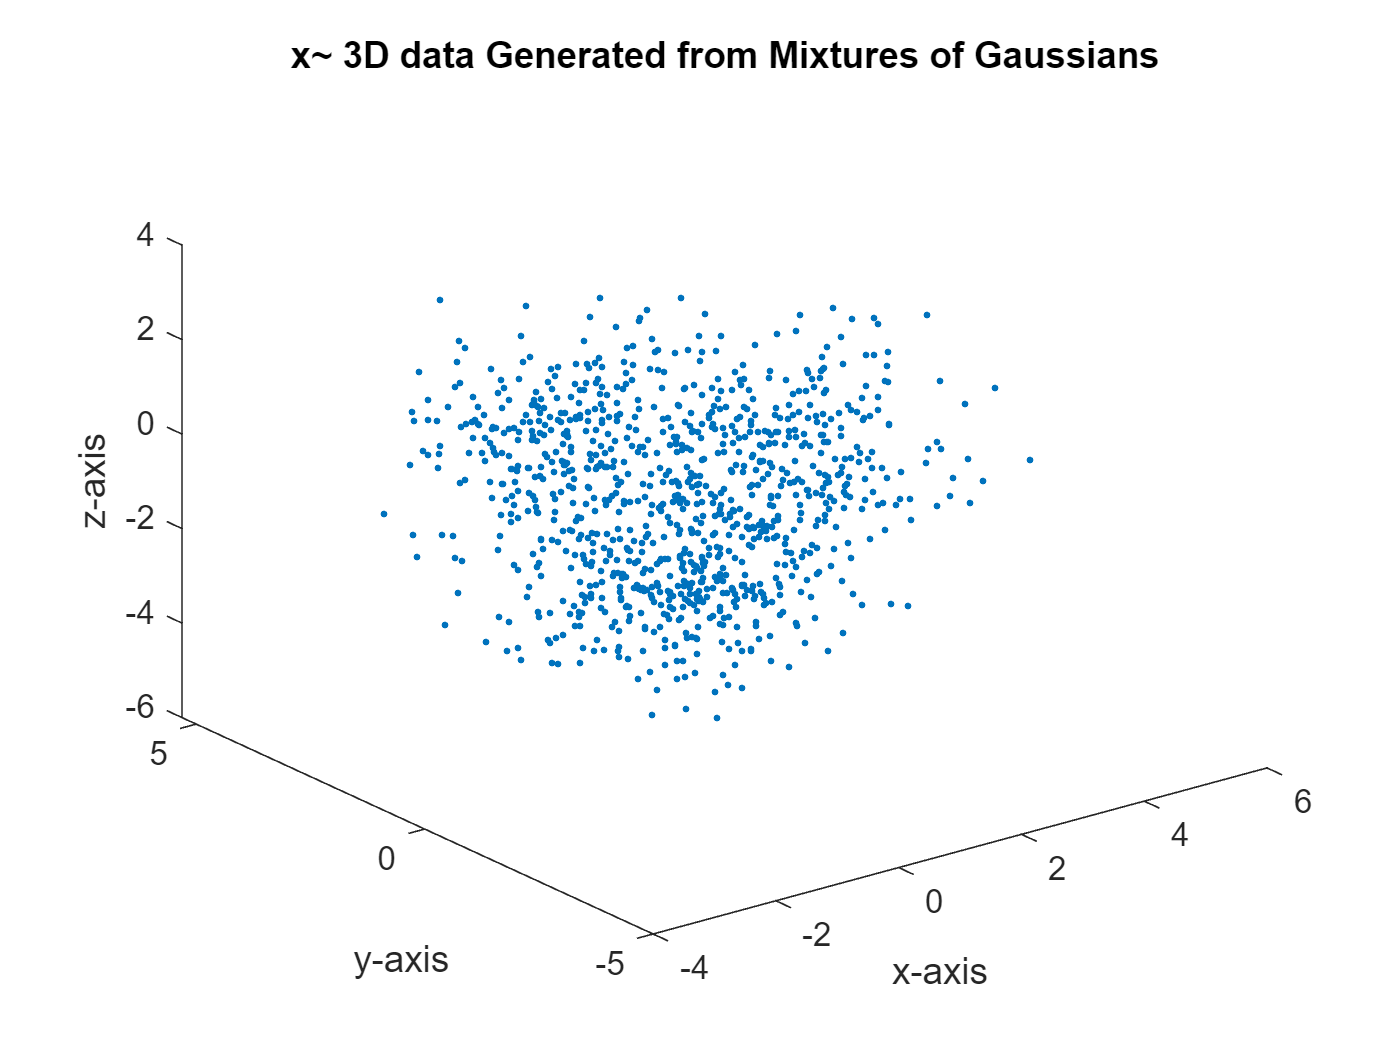


%% 3D case
clear gmmParameters mu sigma
mu=[2 0 0; 0 2 0; 0 0 -2];% 3 normal distributions means of x, y and z axis
sigma(:,:,1)= eye(3); %1st normal distribution covariance
sigma(:,:,2)= eye(3); % 2nd normal distribution covariance
sigma(:,:,3)= eye(3); %3rd normal distribution covariance
% Store parameters in a structure
gmmParameters.meanVectors=mu;
gmmParameters.covMatrices=sigma;
gmmParameters.priors=[0.3 0.3 0.4];%the likelihood of each distribution to be selected
% Generate 3D matrix from 3 mixtures of Gaussians
V_gaussian_3D = generateDataFromGMM_OG(N,gmmParameters,1); 